





H_k = Ca(1,:);
R_k = [8];
P_ko = 1/2*eye(9,9);
S_o = inv(H_k*P_ko*H_k' + R_k);
K_ko = P_ko*H_k'*S_o;
P_kc = (eye(9,9) - K_ko*H_k)*P_ko;
y_o = Ca*P_kc*Ca';
y11 = [sqrt((y_o(1,1)))];
y22 = [sqrt((y_o(2,2)))];

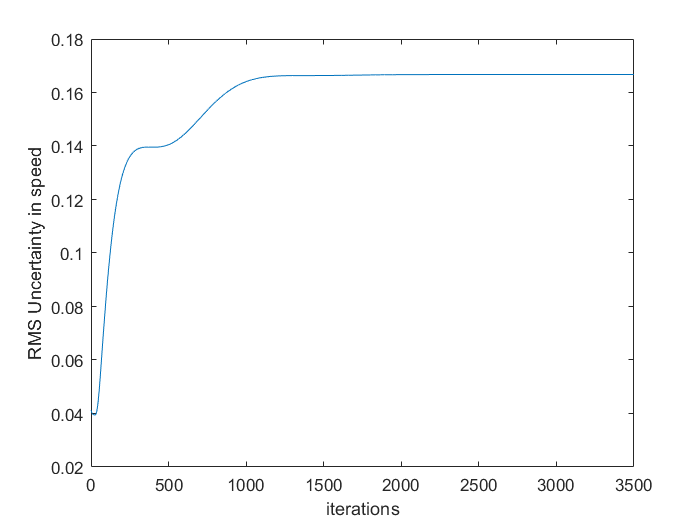


for i = 1:3500
    %%prediction
    P_kp = F*P_kc*F' + Q_bar;
    S = inv(H_k*P_kp*H_k' + R_k);
    K_k = P_kp*H_k'*S;
    %%correction
    P_kc = (eye(9,9) - K_k*H_k)*P_kp;
    x(i) = i;
    y_o = Ca*P_kc*Ca';
    y11(i) = sqrt((y_o(1,1)));
    y22(i) = sqrt(y_o(2,2));
end
figure(1)
plot(x, y11)
xlabel('iterations') 
ylabel('RMS Uncertainty in speed') 

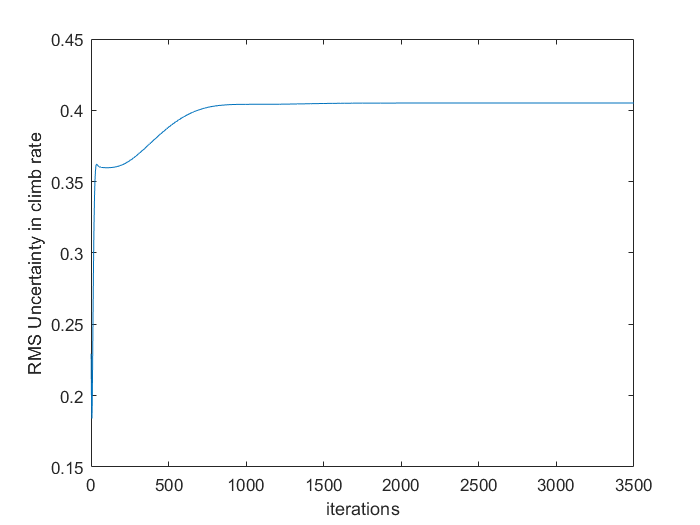

plot(x, y22)
xlabel('iterations') 
ylabel('RMS Uncertainty in climb rate') 




























%%%dare to 
[Ppinf,L_,G_] = dare(F',H_k',Q_bar,R_k)

Ppinf =     9.8095   -0.0580   -0.2206   -0.3488   -5.9368   59.3944   -0.3180   -0.5619    5.9956
   -0.0580    8.7122    0.1480    0.3525    0.1298  -29.9727    0.4250   -0.0295   -2.9943
   -0.2206    0.1480    1.1309    0.0365    9.0615    0.3169    0.0308    0.9031   -0.0586
   -0.3488    0.3525    0.0365    0.8616   -1.9959  -15.1075    0.8156   -0.2811   -1.4826
   -5.9368    0.1298    9.0615   -1.9959  107.9913   12.2599    7.0108   10.0981    0.2162
   59.3944  -29.9727    0.3169  -15.1075   12.2599  922.2464  -10.3520    2.2612   91.9985
   -0.3180    0.4250    0.0308    0.8156    7.0108  -10.3520    6.9976    0.0013   -1.0353
   -0.5619   -0.0295    0.9031   -0.2811   10.0981    2.2612    0.0013    1.0097    0.1252
    5.9956   -2.9943   -0.0586   -1.4826    0.2162   91.9985   -1.0353    0.1252    9.1873


L_ =    0.9979 + 0.0030i
   0.9979 - 0.0030i
   0.9835 + 0.0000i
   0.9835 + 0.0000i
   0.9834 + 0.0028i
   0.9834 - 0.0028i
   0.9409 + 0.0691i
   0.9409 - 0.0691i
   0.6065 + 0.0000i


G_ =     0.0446   -0.0446   -0.0029   -0.0014   -0.0427    0.3897   -0.0017   -0.0041    0.0394


Sinf = inv(H_k*Ppinf*H_k' + R_k);
K_inf = Ppinf*H_k'*S

K_inf =     0.0444
   -0.0447
   -0.0029
   -0.0016
   -0.0419
    0.3918
   -0.0019
   -0.0040
    0.0396


P_cinf = (eye(9,9) - K_inf*H_k)*Ppinf;
var = Ca*P_cinf*Ca'

var =     0.0278   -0.0023
   -0.0023    0.1641


%%%Question3

% for j = 1:50
%     R_k = R_k*1.2
%     [Ppinf,L_,G_] = dare(F',H_k',Q_bar,R_k)
%     Sinf = inv(H_k*Ppinf*H_k' + R_k);
%     K_inf = Ppinf*H_k'*S
%     P_cinf = (eye(9,9) - K_inf*H_k)*Ppinf;
%     var = Ca*P_cinf*Ca'
%     x_R(j) = R_k
%     y(j) = sqrt(var(2,2))
% 
% end
% figure(1)
% plot(x_R,y)
% xlabel('Values of R') 
% ylabel('RMS Uncertainty in climb rate')



















R_k = 1000000;
[Ppinf,L_,G_] = dare(F',H_k',Q_bar,R_k);
Sinf = inv(H_k*Ppinf*H_k' + R_k);
K_inf = Ppinf*H_k'*S;
P_cinf = (eye(9,9) - K_inf*H_k)*Ppinf;
var = Ca*P_cinf*Ca';
sqrt(var(2,2))

ans = 0.4963